maxEpochs = 15;
slice = 5000;
rng(1)

ds = load('LabledData\raw_labled.mat', 'ls');
ds = ds.ls.Labels;
lables = ds.detect_blinks;
dir = ds.Properties.RowNames;


Ds = {};
for i = 1:numel(dir)    
    raw_data = csvread(dir{i},1,1);
    filtered_data = hl_filter(raw_data(:,1));
    lable = lables(i);
    masked = getmask({filtered_data,lable{1,1}});
    Ds{i} = masked;  
end

chopedDs = {};
for i = 1:numel(Ds)
    for j = 1:(slice-1):numel(Ds{i}{1})-(slice-1)
        chopedDs{end+1} = {Ds{i}{1}(j:j+slice-1).',Ds{i}{2}(j:j+slice-1).'};        
    end
end

XTrain = {};
YTrain = {};

for i = 1:numel(chopedDs)
    XTrain{end+1} = chopedDs{i}{1};
    YTrain{end+1} = chopedDs{i}{2};
end
XTrain;
YTrain;
[trainIdx,~,testIdx] = dividerand(numel(XTrain),0.7,0,0.3);

XTest = XTrain(testIdx);
YTest = YTrain(testIdx);
XTrain = XTrain(trainIdx);
YTrain = YTrain(trainIdx);

trainDs = {XTrain, YTrain};
testDs = {XTest, YTest};


tallTrainSet = tall(trainDs);
tallTestSet = tall(testDs);
trainData = gather(tallTrainSet);
testData = gather(tallTestSet);

% for i = 1:numel(XTrain)
%     mu = mean([XTrain{i}],2);
%     sig = std([XTrain{i}],0,2);
%     XTrain{i} = (XTrain{i} - mu) ./ sig;
% end

% results = bayesopt(objectFunction,optimVars,'UseParallel',true);

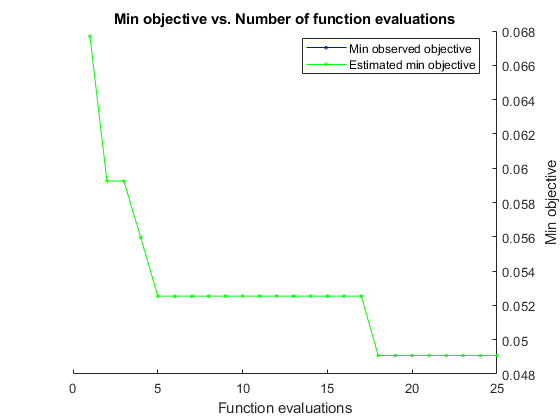

  MException with properties:

    identifier: 'MATLAB:parallel:future:FetchNextFutureErrored'
       message: 'The function evaluation completed with an error.'
         cause: {[1×1 ParallelException]}
         stack: [6×1 struct]
    Correction: []



Error using trainNetwork
Out of memory.

Error in objectFunctionTCN/valErrorFun (line 34)
        net = trainNetwork(XTrain,YTrain,layers,options);

Error in bayesoptim.callObjFcnParallel>callObjNormallyParallel (


optimVars = [
    %numFilters, filterSize, numBlocks, dropoutFactor
    optimizableVariable('numFilters',[2 32],'Type','integer')
    optimizableVariable('filterSize',[7 33],'Type','integer')
    optimizableVariable('numBlocks',[1 8],'Type','integer')
    optimizableVariable('dropoutFactor',[0.00 0.2],'Type','real')
%     optimizableVariable('miniBatchSize',[2 16],'Type','integer')    
    optimizableVariable('learningrate',[1e-4 1e-1],'Type','real',"Transform","log")];

    objectFunction = objectFunctionTCN(trainDs, testDs,  maxEpochs);
    
% optimizer
BayesObject = bayesopt(objectFunction, optimVars, ...
    'MaxTime',10*60*60, ...
    'Verbose',0,...
    "UseParallel",true,...
    'IsObjectiveDeterministic',true, ...
    'ParallelMethod',"clipped-model-prediction",...
    'MaxObjectiveEvaluations',90,...
    'ExplorationRatio',0.6,...
    'AcquisitionFunctionName', 'expected-improvement-per-second-plus');

optVars = bestPoint(BayesObject);



    % Evaluate and train the network with the optimal parameters
% [valError,~,net, YPred, YTest] = BayesObject.ObjectiveFcn(optVars,1);

TX = {};
for i = 1:numel(testDs)
    TX{end+1} = testDs{i}{1};
end


TY = [];
Y = [];
YTest = YTest.';
for i = 1:numel(testDs)
    TY = [TY;YTest{i}];
    Y = [Y;YPred{i}];
end

confusionchart(TY(:),Y(:),'Normalization','column-normalized');

optVars = bestPoint(BayesObject);

save("8604\hyperParameter\TCN_0.mat","optVars","-mat");
